### **Иван Шаламов, 551 группа. ЛР 7 (Метод Контрольных Объемов), 2021.**

clc;
close all;
clear;
opengl software;

### **Практическая и исследовательская часть.**

Входные параметры.

TextSize = 20;
k = 1.4; % показатель адиабаты
Cp = 1006.43;
R = (k - 1) / k * Cp;
p_inf = 101325;
T_inf = 300;
M_inf = 3;
T0_inf = T_inf / tau_ot_M(M_inf, k);
V_inf = V_ot_M_T0_R_k(M_inf, T0_inf, R, k);

Загрузка и конвертация сетки. 

**Задача:** Натекание сверхзвукового потока воздуха на ромбовидный профиль малого утолщения под малым углом атаки. Поток воздуха с числом Маха M∞ = 3 , p∞ = 101325 Па и T∞ = 300 К натекает на ромбовидный профиль, расположенный под углом α = 5°.

pdeToolMesh = load('mesh.mat');
[points, faces, leftCell, rightCell, numIntFace, numCell, numFaceInBc, ...
    startFaceInBc] = convertMeshElementBasedToFaceBsed(pdeToolMesh.t, pdeToolMesh.e, ...
    pdeToolMesh.p);
elementsByPoints = convertMeshFaceBsedToElementBased(faces, leftCell, rightCell, ...
    numIntFace, numCell);
numFace = length(leftCell);
numBcFace = numFace - numIntFace;

Расчет геометрических параметров сетки (Vol, nx, ny, Sf, dx).

[Sf, nx, ny, xf, yf, Vol, xC, yC, dx] = solveMeshData(points, faces, leftCell, ...
    rightCell, numIntFace, numCell);

Дальнейшие параметры.

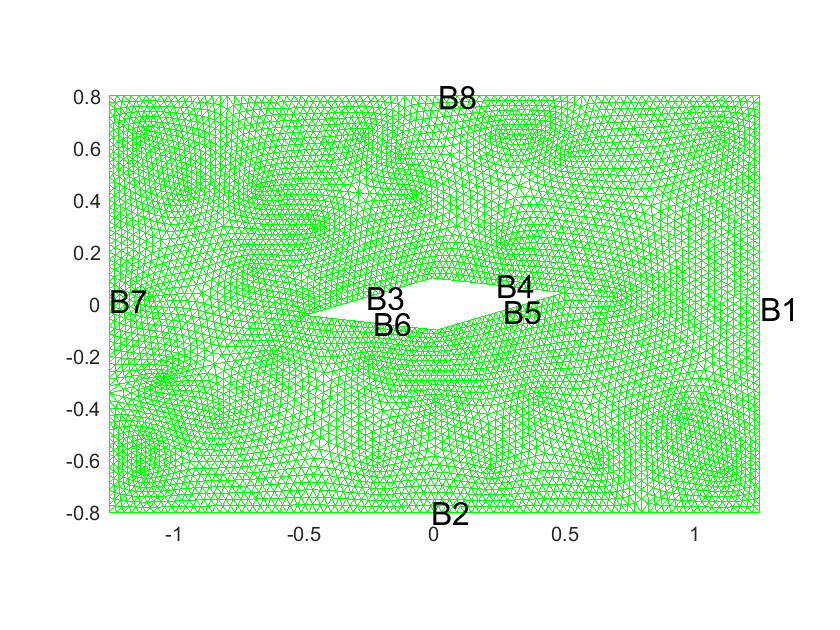

% Создаем поля переменных, фиктивные ячейки, инициализируем параметры потока:
[u1, u2, u3, u4] = initializationField(p_inf, V_inf, 0.0, T_inf, k, R, ...
    numCell+numBcFace);

% Добавляем индексы фиктивных ячеек как парных:
rightCell((numIntFace+1):numFace) = ((numIntFace+1):numFace) - numIntFace + numCell;

% Указываем список граничных условий (их типы), номер можно посмотреть в
% тулбоксе, где генерировалась сетка ('SuperSonicInlet' 'SuperSonicOutlet'
% 'wall')
bcType = cellstr(char('SuperSonicOutlet', 'wall', 'wall', 'wall', 'wall', 'wall', ...
    'SuperSonicInlet', 'wall'));
numBc = length(numFaceInBc);

% Выводим сетку:
figure(1);
plotUnstructuredDataAndMesh(points, faces', elementsByPoints, numFaceInBc, ...
    startFaceInBc, [], 'mesh');

Основной цикл.

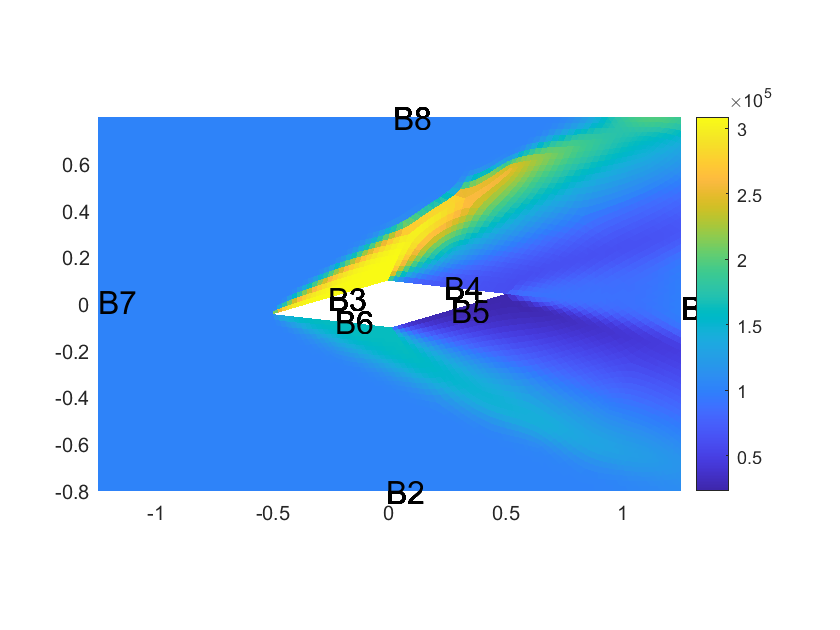

NumTimeStep = 1000; % число шагов по времени
plot_interval = 100; % интервал вывода графиков в шагах
CFL = 0.75;
t(1) = 0;
plot_time = plot_interval;

for i=1:NumTimeStep
    
    % Добавляем граничные условия в фиктивных ячейках:
    for bc = 1:numBc
        
        type = char(bcType(bc));
        
        switch (type)
            
            case {'SuperSonicOutlet'}
                
                [u1, u2, u3, u4] = addSuperSonicOutletBc(u1, u2, u3, u4, ...
                    leftCell, rightCell, numFaceInBc(bc), startFaceInBc(bc));
                
            case {'SuperSonicInlet'}
                
                [u1, u2, u3, u4] = addSuperSonicInletBc(u1, u2, u3, u4, ...
                    leftCell, rightCell, numFaceInBc(bc), startFaceInBc(bc), ...
                    p_inf, V_inf, 0.0, T_inf, R, k);
                
            case {'wall'}
                
                [u1, u2, u3, u4] = addWallBc(u1, u2, u3, u4, leftCell, ...
                    rightCell, numFaceInBc(bc), startFaceInBc(bc));
                
            otherwise
                
                [u1, u2, u3, u4] = addWallBc(u1, u2, u3, u4, leftCell, ...
                    rightCell, numFaceInBc(bc), startFaceInBc(bc));
                
        end
        
    end
    
    % Рассчитываем временной шаг:
    rhoV_mod = (u2.^2 + u3.^2).^0.5;
    dt = SolveTimeStepExplicitEiler(u1(1:numCell), rhoV_mod(1:numCell), ...
        u4(1:numCell), dx/2, CFL, k);
    t(i+1) = t(i) + dt;
    
    % Рассчитываем потоки:
    % Поворот системы координат:
    [v1L, v2L] = rotateVectorToNormal(u2(leftCell), u3(leftCell), nx, ny);
    [v1R, v2R] = rotateVectorToNormal(u2(rightCell), u3(rightCell), nx, ny);
    
    % Функция расчета потоков:
    [F1, F2, F3, F4, iteration] = SolveFluxExacRieman2D(u1(leftCell), v1L, v2L, ...
        u4(leftCell), u1(rightCell), v1R, v2R, u4(rightCell), k);
    F1 = F1';
    F2 = F2';
    F3 = F3';
    F4 = F4';
    
    % Поворот обратно:
    [F2, F3] = rotateVectorToCartesian(F2, F3, nx, ny);
    
    % Выполняем шаг по времени:
    [u1, u2, u3, u4] = solveEvolution2D(F1.*Sf, F2.*Sf, F3.*Sf, F4.*Sf, ...
        u1, u2, u3, u4, leftCell, rightCell, dt, Vol, numIntFace);
    
    if i == plot_time
        
        figure(2);
        rho = u1(1:numCell);
        vx = u2(1:numCell)./rho;
        vy = u3(1:numCell)./rho;
        p = (k - 1) * (u4(1:numCell) - 0.5 * (vx.^2 + vy.^2).*rho);
        T = p./(R * rho);
        plotUnstructuredDataAndMesh(points, faces', elementsByPoints, numFaceInBc, ...
            startFaceInBc, p, 'data'); % 'rho', '(vx.^2+vy.^2).^0.5', 'T'
        plot_time = plot_time + plot_interval;
        pause(0.001);
        
    end
    
end

### **Использованные функции.**

T / T₀.

function tau = tau_ot_M(M, k)

tau = (1 + (k - 1) / 2.*M.^2).^(-1);

end

Скорость газа от числа Маха.

function V = V_ot_M_T0_R_k(M, T0, R, k)

V = Vmax_ot_T0(T0, R, k) * V_na_Vmax_ot_M(M, k);

end

Максимально возможная скорость истечения.

function f = Vmax_ot_T0(T0, R, k)

f = (2 * k / (k - 1) * R * T0).^(0.5);

end

V / Vmax.

function f = V_na_Vmax_ot_M(M, k)

f = (((k - 1) / 2.*M.^2)./(1 + (k - 1) / 2.*M.^2)).^(0.5);

end

Функция конвертирует сетку из element-based неструктурированной в face-based.

function [points, faces, leftCell, rightCell, numIntFace, numCell, numFaceInBc, ...
    startFaceInBc] = convertMeshElementBasedToFaceBsed(elementsByPoints, boundary, p)

% Convert to face-based notation for all triang:
numCell = length(elementsByPoints(1,:));
faces = [];
leftCell = [];
rightCell = [];

for tri = 1:numCell
    
    tri;
    numFaceInCell = 3;
    
    for f = 1:(numFaceInCell-1)
        
        p1 = elementsByPoints(f, tri);
        p2 = elementsByPoints(f+1, tri);
        
        % Find right (ищем, есть ли в массиве faces грани с такими же
        % узлами, но в обратном порядке (может быть только не более 1 для 2D сеток), и
        % ячейка с такой гранью будет соседней к данной):
        if(~isempty(faces))
            
            indFaceRightCell = find(faces(:,1) == p2 & faces(:,2) == p1);
            
        else
            
            indFaceRightCell = [];
            
        end
        
        indFaceRightCell;
        
        % Если не нашли, то зиписываем и устанавливаем leftCell.
        % Eсли нашли, то значение в массиве leftCell для этой грани уже
        % установлено верно, и устанавливаем для этой грани rightCell как
        % tri. Эта грань будет внутренней:
        if(indFaceRightCell)
            
            rightCell(indFaceRightCell) = tri;
            
        else
            
            % Добавляем грань p1-p2 в массив faces, в массив левых ячеек
            % добавляем индекс ячейки i:
            faces(end+1, 1) = p1; % push_back
            faces(end, 2) = p2; % set
            leftCell(end+1) = tri; % push_back
            
        end
        
    end
    
    % То же для последней грани в ячейке:
    p1 = elementsByPoints(numFaceInCell, tri);
    p2 = elementsByPoints(1, tri);
    indFaceRightCell = find(faces(:,1) == p2 & faces(:,2) == p1);
    
    if(indFaceRightCell)
        
        rightCell(indFaceRightCell) = tri;
        
    else
        
        faces(end+1, 1) = p1; % push_back
        faces(end, 2) = p2; % set
        leftCell(end+1) = tri; % push_back
        
    end
    
end

% Там, где rightCell осталось == 0 - это граничные грани, размер rightCell
% делаем такой же, как и у leftCell:
if(length(rightCell) < length(leftCell))
    
    rightCell(length(leftCell)) = 0;
    
end

% Сортируем грани сначала внутренние, потом граничные 1-го, потом 2-го и
% т.д. FIXME: сделать сортировку с алгоритмом уменьшения ширины ленты.
% Подсчитываем, сколько всего ГУ и сколько граней в каждом:
numBc = max(boundary(5,:));
numFace = length(faces(:,1));
numBcFace = length(boundary(5,:));
numIntFace = numFace - numBcFace;
startFaceInBc(1) = numIntFace + 1;

for bc = 1:numBc-1
    
    ind  = find(boundary(5,:) == bc);
    size = length(ind);
    numFaceInBc(bc) = size;
    startFaceInBc(bc+1) = startFaceInBc(bc) + numFaceInBc(bc);
    
end

size = length(find(boundary(5,:) == numBc));
numFaceInBc(numBc) = size;

% Sort face:
for bc = 1:numBc
    
    ind  = find(boundary(5,:) == bc);
    
    for f = 1:numFaceInBc(bc)
        
        indBc = ind(f);
        
        if(boundary(7,indBc) == 1)
            
            p1 = boundary(2,indBc);
            p2 = boundary(1,indBc);
            
        else
            
            p1 = boundary(1,indBc);
            p2 = boundary(2,indBc);
            
        end
        
        indFace1 = find(faces(:,1) == p1 & faces(:,2) == p2);
        indFace2 = startFaceInBc(bc) + f - 1;
        
        % Обмен:
        L = leftCell(indFace1);
        R = rightCell(indFace1);
        faces(indFace1,1) = faces(indFace2,1);
        faces(indFace1,2) = faces(indFace2,2);
        leftCell(indFace1) = leftCell(indFace2);
        rightCell(indFace1) = rightCell(indFace2);
        
        faces(indFace2,1) = p1;
        faces(indFace2,2) = p2;
        leftCell(indFace2) = L;
        rightCell(indFace2) = R;
        
    end
    
end

% Здесь нужно реализовать сортировку ячеек и граней для уменьшения
% ширины ленты и "порядок верхнего треугольника" (up-triang order).

points = p';
leftCell = leftCell';
rightCell = rightCell';
numFaceInBc = numFaceInBc';
startFaceInBc = startFaceInBc';

end

% Входные параметры (импортируют данные о сетке из pdetool):
% elementsByPoints - массив описывает элемент набором точек (узлов),
% boundary - описывающий границу массив,
% p - массив точек.
%
% Выходные параметры:
% points - массив координат точек,
% faces - массив, описывающий грани,
% leftCell - массив содержит левые ячейки к заданной грини,
% rightCell - правые ячейки,
% numIntFace - число внутренних граней,
% numCell - количество внутренних ячеек,
% numFaceInBc - количество граней в границе,
% startFaceInBc - стартовый номер граничной гране в общем списке.

Функция конвертирует сетку из face-based неструктурированной в element-based.

function elementsByPoints = convertMeshFaceBsedToElementBased(faces, leftCell, ...
    rightCell, numIntFace, numCell)

numFace = length(leftCell);
numFaceInCell = 3; % FIXME: ячейка может быть и не только треугольником.
elementsByFace = zeros(numCell, numFaceInCell);

for f=1:numFace
    
    L = leftCell(f);
    R = rightCell(f);
    ind = find(elementsByFace(L,:)==0, 1, 'first');
    elementsByFace(L,ind) = f;
    
    if(f <= numIntFace)
        
        ind = find(elementsByFace(R,:)==0, 1, 'first');
        elementsByFace(R,ind) = -f;
        
    end
    
end

elementsByPoints = zeros(numCell, 3);

for c = 1:numCell
    
    numFaceInCell = 3;
    
    for f=1:(numFaceInCell-1)
        
        face = elementsByFace(c,f);
        
        if (face > 0) % left face
            
            p1 = faces(face,1);
            p2 = faces(face,2);
            
        else
            
            p1 = faces(-face,2);
            p2 = faces(-face,1);
            
        end
        
        indP = find(elementsByPoints(c,:)==p1, 1, 'first');
        
        if (isempty(indP))
            
            ind0 = find(elementsByPoints(c,:)==0, 1, 'first');
            elementsByPoints(c,ind0) = p1;
            
        end
        
        indP = find(elementsByPoints(c,:)==p2, 1, 'first');
        
        if (isempty(indP))
            
            ind0 = find(elementsByPoints(c,:)==0, 1, 'first');
            elementsByPoints(c,ind0) = p2;
            
        end
        
    end
    
end

end

% Входные параметры:
% faces - массив, описывающий грани,
% leftCell - массив содержит левые ячейки к заданной грини,
% rightCell - правые ячейки,
% numIntFace - число внутренних граней,
% numCell - количество внутренних ячеек.
%
% Выходные параметры:
% elementsByPoints - массив описывает элемент набором точек (узлов).

Функция расчитывает геометрические параметры сетки.

function [Sf, nx, ny, xf, yf, Vol, xC, yC, dx] = solveMeshData(points, faces, ...
    leftCell, rightCell, numIntFace, numCell)

% Calculate face normals:
p1 = faces(:,1);
p2 = faces(:,2);
x1 = points(p1,1);
y1 = points(p1,2);
x2 = points(p2,1);
y2 = points(p2,2);
Sf = ((x2 - x1).^2 + (y2 - y1).^2).^0.5;
nx = (y2 - y1)./Sf;
ny = -(x2 - x1)./Sf;
xf = 0.5 * (x2 + x1);
yf = 0.5 * (y2 + y1);

% Calculate face centers:
xC = zeros(numCell,1);
yC = zeros(numCell,1);
numFaceInCell = 3;
numFace = length(leftCell);

for f=1:numFace
    
    xC(leftCell(f)) = xC(leftCell(f)) +  xf(f);
    yC(leftCell(f)) = yC(leftCell(f)) +  yf(f);
    
    if(f <= numIntFace)
        
        xC(rightCell(f)) = xC(rightCell(f)) + xf(f);
        yC(rightCell(f)) = yC(rightCell(f)) + yf(f);
        
    end
    
end

xC = xC./numFaceInCell;
yC = yC./numFaceInCell;

% Check normals:
numModifNormal = 0;
for f=1:numFace
    dr_x = xf(f) - xC(leftCell(f));
    dr_y = yf(f) - yC(leftCell(f));
    dot = dr_x*nx(f) + dr_y*ny(f);
    if(dot<0)
        numModifNormal = numModifNormal +1;
        temp = faces(f,1);
        faces(f,1) = faces(f,2);
        faces(f,2) = temp;
        nx(f) = -nx(f);
        ny(f) = -ny(f);
    end
end

% Calculate volume:
Vol = zeros(numCell, 1);

for f=1:numFace
    
    temp = xf(f) * nx(f) * Sf(f);
    Vol(leftCell(f)) = Vol(leftCell(f)) + temp;
    
    if (f <= numIntFace)
        
        Vol(rightCell(f)) = Vol(rightCell(f)) - temp;
        
    end
    
end

% Рассчитываем радиус вписанной окружности. FIXME: для начала берем как
% диаметр круга равной площади.
dx = (4 / pi * Vol).^0.5;

end

% Входные параметры:
% points - массив координат точек,
% faces - массив, описывающий грани,
% leftCell - массив содержит левые ячейки к заданной грани,
% rightCell - правые ячейки,
% numIntFace - число внутренних граней,
% numCell - количество внутренних ячеек.
%
% Выходные параметры:
% Sf - площадь (длина) граней,
% nx - x-компонента вектора нормали грани,
% ny - y-компонента вектора нормали грани,
% xf - x-компонента центра грани,
% yf - y-компонента центра грани,
% Vol - объем (площадь в 2D случае) ячейки,
% xC - x-компонента центра ячейки,
% yC - y-компонента центра ячейки,
% dx - диаметр вписанной окружности в ячейку.

Функция производит инициализацию полей.

function [u1, u2, u3, u4] = initializationField(pres, vx, vy, T, k, Rgas, numCell)

u1 = ones(numCell,1) * pres / (Rgas * T);
u2 = u1 * vx;
u3 = u2 * vy;
u4 = pres / (k - 1) + 0.5 * u1 * (vx * vx + vy * vy);

end

function plotUnstructuredDataAndMesh(points, faces, elementsByPoints, numFaceInBc, ...
    startFaceInBc, cdata, plotType)

% Визуалиция сетки:
switch (plotType)
    
    case {'data'}
        
        patch('Faces', elementsByPoints, 'Vertices', points, 'FaceVertexCData', ...
            cdata, 'FaceColor', 'flat', 'EdgeColor', 'none', 'CDataMapping', 'scaled');
        colorbar;
        
    case {'mesh'}
        
        patch('Faces', elementsByPoints, 'Vertices', points, 'FaceColor', 'w', ...
            'EdgeColor', 'g');
        
    otherwise
        
        patch('Faces', elementsByPoints, 'Vertices', points, 'FaceColor', 'w', ...
            'EdgeColor', 'g');
        
end

numBc = length(numFaceInBc);

for bc = 1:numBc
    
    indP1 = faces(1,startFaceInBc(bc):(startFaceInBc(bc)+numFaceInBc(bc) - 1));
    x = mean(points(indP1,1));
    y = mean(points(indP1,2));
    text(x, y, ['B', num2str(bc)], 'FontSize', 16);
    
end

axis equal tight;

end

% Входные параметры:
% points - массив координат точек,
% faces - массив, описывающий грани,
% leftCell - массив содержит левые ячейки к заданной грани,
% rightCell - правые ячейки,
% numIntFace - число внутренних граней,
% numCell - количество внутренних ячеек,
% elementsByPoints - сетка в element-based нотации,
% numFaceInBc - количество граней в границе,
% startFaceInBc - стартовый номер граничной грани в общем списке,
% cdata - массив параметров данных,
% plotType - тип вывода 'mesh' - просто сетка 'data' (данные).

Функция заносит в фиктивные ячейки параметры, соответсвующие граничному условию addSuperSonicOutletBc.

function [u1, u2, u3, u4] = addSuperSonicOutletBc(u1, u2, u3, u4, leftCell, ...
    rightCell, num, start)

for f=start:(start+num-1)
    
    left = leftCell(f);
    right = rightCell(f);
    u1(right) = u1(left);
    u2(right) = u2(left);
    u3(right) = u3(left);
    u4(right) = u4(left);
    
end

end

Функция заносит в фиктивные ячейки параметры, соответсвующие граничному условию addSuperSonicInletBc.

function [u1, u2, u3, u4] = addSuperSonicInletBc(u1, u2, u3, u4, ~, ...
    rightCell, num, start, p_inf, vx_inf, vy_inf, T_inf, R, k)

rho = p_inf / (R * T_inf);
rhoV = rho * vx_inf;
rhoU = rho * vy_inf;
rhoE = p_inf / (k - 1) + 0.5 * rho * (vx_inf * vx_inf + vy_inf * vy_inf);

for f = start:(start+num-1)
    
    right = rightCell(f);
    u1(right) = rho;
    u2(right) = rhoV;
    u3(right) = rhoU;
    u4(right) = rhoE;
    
end

end

Функция заносит в фиктивные ячейки параметры, соответсвующие граничному условию.

function [u1, u2, u3, u4] = addWallBc(u1, u2, u3, u4, leftCell, rightCell, num, start)

for f = start:(start+num-1)
    
    left = leftCell(f);
    right = rightCell(f);
    u1(right) = u1(left);
    u2(right) = -u2(left);
    u3(right) = -u3(left);
    u4(right) = u4(left);
    
end

end

Функция расчета шага по времени для явной схемы Эйлера.

function dt = SolveTimeStepExplicitEiler(U1, U2, U3, dx, Courant, gamma)

rho = U1;
u = U2./rho;
p = (gamma - 1) * (U3 - 0.5 * (u.^2).*rho);
c = sqrt(gamma * p./rho);
dt = min(Courant * dx./(abs(u) + c));

end

Функция поворота системы координат, проекция на нормаль.

function [v1, v2] = rotateVectorToNormal(u1, u2, nx, ny)

v1 = u1.*nx + u2.*ny;
v2 = -u1.*ny + u2.*nx;

end

Функция расчета потока на грани контрольного объема с использованием точного решения о распаде разрыва, использует консервативные переменные.

function [F1, F2, F3, F4, iteration] = SolveFluxExacRieman2D(U1L, U2L, U3L, ...
    U4L, U1R, U2R, U3R, U4R, Gamma)

% Переводим в физические переменные:
left_density = U1L;
right_density = U1R;
left_velocity = U2L./left_density;
right_velocity = U2R./right_density;
v3L = U3L./left_density;
v3R = U3R./right_density;
left_pressure = (Gamma - 1) * (U4L - 0.5 * (left_velocity.^2 + v3L.^2).*left_density);
right_pressure = (Gamma - 1) * (U4R - 0.5 * (right_velocity.^2 + ...
    v3R.^2).*right_density);

MaxIteration = 20; % максимальное число итераций
TOL = 1e-8;
lambda = 0; % линия на грани КО

len = length(U1L);
rho = zeros(1, len);
u = zeros(1, len);
p = zeros(1, len);

for i = 1:len
    
    [rho(i), u(i), p(i), ~, iteration] = ExacRiemanSolver(left_density(i), ...
        left_velocity(i), left_pressure(i), right_density(i), right_velocity(i), ...
        right_pressure(i), Gamma, lambda, MaxIteration, TOL);

end

% Рассчитываем потоки:
F1 = rho.*u;
F2 = (rho.*u).*u + p;
ind = (F1 >= 0);
v3 = (v3L').*ind + (v3R').*(~ind);
F3 = F1.*v3;
F4 = (p./(Gamma - 1) + rho.*(u.^2 + v3.^2) / 2 + p).*u;

end

% Входные параметры:
% U1L, U2L, U3L, U4L - вектор консервативных переменных слева,
% U1R, U2R, U3R, U4R - вектор консервативных переменных справа.
%
% Выходные параметры:
% F1, F2, F3, F4 - вектор потока на грани КО,
% iteration - выполненое количество итераций.

Функция расчета параметров задачи Римана для уравнений Эйлера (задача о распаде произвольного разрыва) точным подходом.

Используя аналитические соотношения, можно составить неленейное уравнение для определения давления на контактном разрыве, решив его итерационным методом Ньютона (метод касательных), можно пересчитать остальные параметры во всех областях.

function [ret_density, ret_velocity, ret_pressure, is_left_of_contact, ...
    iteration] = ExacRiemanSolver(left_density, left_velocity, left_pressure, ...
    right_density, right_velocity, right_pressure, Gamma, lambda, MaxIteration, TOL)

iteration = 0;

% Solve Sound Velosity for Left and Right:
left_soundspeed = sqrt(Gamma * left_pressure / left_density);
right_soundspeed = sqrt(Gamma * right_pressure / right_density);

% Проверяем образуется ли вакуум (образуется редко):
left_vacuum_front_speed = left_velocity + 2.0 * left_soundspeed / (Gamma - 1.0);
right_vacuum_front_speed = right_velocity - 2.0 * right_soundspeed / (Gamma - 1.0);
critical_speed = left_vacuum_front_speed - right_vacuum_front_speed;

if (critical_speed < 0.0) % образуется зона вакуума
    
    left_head_speed = left_velocity - left_soundspeed;
    left_tail_speed = left_vacuum_front_speed;
    right_head_speed = right_velocity + right_soundspeed;
    right_tail_speed = right_vacuum_front_speed;
    
    is_left_of_contact = lambda < left_tail_speed;
    
    if (is_left_of_contact) % определяем, где находится искомая линия lambda,
        % слева ли от контактного разрыва
        
        if (lambda < left_head_speed)
            
            ret_density = left_density;
            ret_velocity = left_velocity;
            ret_pressure = left_pressure;
            
        else
            
            % left_rarefaction (4.56)
            temp1 = 2.0 / (Gamma + 1.0) + (Gamma - 1.0) / (Gamma + 1.0) / ...
                left_soundspeed * (left_velocity - lambda);
            ret_density = left_density * temp1^(2.0 / (Gamma - 1.0));
            ret_pressure = left_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
            ret_velocity = 2.0 / (Gamma + 1.0) * (left_soundspeed + ...
                (Gamma - 1.0) / 2.0 * left_velocity + lambda);
            
        end
        
    else
        
        if (lambda > right_tail_speed)
            
            if (lambda > right_head_speed)
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else
                
                % right_rarefaction (4.63)
                temp1 = 2.0 / (Gamma + 1.0) - (Gamma - 1.0) / (Gamma + 1.0) / ...
                    right_soundspeed * (right_velocity - lambda);
                ret_density = right_density * temp1^(2.0 / (Gamma - 1.0));
                ret_pressure = right_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                ret_velocity = 2.0 / (Gamma + 1.0) * (-right_soundspeed + ...
                    (Gamma - 1.0) / 2.0 * right_velocity + lambda);
                
            end
            
        else
            
            % u resides inside vaccum
            ret_density = 0.0;
            ret_velocity = 0.0;
            ret_pressure = 0.0;
            
        end
        
    end
    
else
    
    % Решение итерационным способом:
    % Начальное приближение:
    % PVRS (9.20)
    
    p_star = 0.5 * (left_pressure + right_pressure) + 0.125 * (left_velocity - ...
        right_velocity) * (left_density + right_density) * (left_soundspeed + ...
        right_soundspeed);
    p_star = max(p_star, TOL);
    
    pMin = min(left_pressure, right_pressure);
    pMax = max(left_pressure, right_pressure);
    
    if (p_star > pMax)
        
        % TSRS (9.42)
        temp1 = sqrt((2.0 / (Gamma + 1.0) / left_density) / (p_star + (Gamma - ...
            1.0) / (Gamma + 1.0 ) * left_pressure));
        temp2 = sqrt((2.0 / (Gamma + 1.0) / right_density) / (p_star + (Gamma - ...
            1.0) / (Gamma + 1.0) * right_pressure));
        p_star = (temp1 * left_pressure + temp2 * right_pressure + (left_velocity - ...
            right_velocity)) / (temp1 + temp2);
        p_star = max(p_star, TOL);
        
    else
        
        if (p_star < pMin)
            
            % TRRS (9.32)
            temp1 = (Gamma - 1.0) / (2.0 * Gamma);
            p_star = ((left_soundspeed + right_soundspeed + 0.5 * (Gamma - 1.0) * ...
                (left_velocity - right_velocity)) / (left_soundspeed / ...
                left_pressure^temp1 + right_soundspeed / ...
                right_pressure^temp1))^(1.0 / temp1);
            
        else
            
            % p_star = PVRS
            
        end
        
    end
    
    % Основной цикл для давления:
    for iteration = 1:MaxIteration
        
        % LEFT
        
        % Solve temp value
        temp1 = sqrt((2.0 / (Gamma + 1.0) / left_density) / (p_star + ...
            (Gamma - 1.0) / (Gamma + 1.0) * left_pressure));
        
        % Solve function 4.6 4.7
        if p_star <= left_pressure
            
            f1 = 2.0 / (Gamma - 1.0) * left_soundspeed * ((p_star / ...
                left_pressure)^((Gamma - 1.0) / (2.0 * Gamma)) - 1.0);
            
        else
            
            f1 = (p_star - left_pressure) * temp1;
            
        end
        
        % Solve derivates 4.37
        if p_star<=left_pressure
            
            f_d = (p_star / left_pressure)^(-(Gamma + 1.0) / (2.0 * Gamma)) / ...
                (left_density * left_soundspeed);
            
        else
            
            f_d = temp1 * (1.0 - 0.5 * (p_star - left_pressure) / (p_star + ...
                (Gamma - 1.0) / (Gamma + 1.0) * left_pressure));
            
        end
        
        % RIGHT
        
        temp1 = sqrt((2.0 / (Gamma + 1.0) / right_density) / (p_star + ...
            (Gamma - 1.0) / (Gamma + 1.0) * right_pressure));
        
        % Solve function 4.6 4.7
        if p_star <= right_pressure
            
            f2 = 2.0 / (Gamma - 1.0) * right_soundspeed * ((p_star / ...
                right_pressure)^((Gamma - 1.0) / (2.0 * Gamma)) - 1.0);
            
        else
            
            f2 = (p_star - right_pressure) * temp1;
            
        end
        
        % Solve derivates
        if p_star <= right_pressure
            
            f_d = f_d + (p_star / right_pressure)^(-(Gamma + 1.0) / (2.0 * Gamma)) / ...
                (right_density * right_soundspeed);
            
        else
            
            f_d = f_d + temp1 * (1.0 - 0.5 * (p_star - right_pressure) / (p_star + ...
                (Gamma - 1.0) / (Gamma + 1.0) * right_pressure));
            
        end
        
        p_New = p_star - (f1 + f2 - (left_velocity - right_velocity)) / f_d;
        
        if (abs(p_New - p_star) / (0.5 * abs(p_New + p_star)) < TOL)
            
            break;
            
        end
        
        p_star = p_New;
        
    end
    
    % Calculate star speed */
    star_speed = 0.5 * (left_velocity + right_velocity) + 0.5 * (f2 - f1);
    
    % Calculate other star values */
    
    % Left
    if (p_star >= left_pressure)
        
        % SHOCK
        left_star_density = left_density * (p_star / left_pressure + (Gamma - 1.0) / ...
            (Gamma + 1.0)) / ((Gamma - 1.0) / (Gamma + 1.0) * p_star / ...
            left_pressure + 1.0);
        left_tail_speed = left_velocity - left_soundspeed * sqrt((Gamma + 1.0) / ...
            (2.0 * Gamma) * p_star / left_pressure + (Gamma - 1.0) / (2.0 * Gamma));
        left_head_speed = left_tail_speed;
        
    else  % left_wave_ == kRarefaction
        
        left_star_density = left_density * (p_star / left_pressure)^(1.0 / Gamma);
        left_head_speed = left_velocity - left_soundspeed;
        left_tail_speed = star_speed - sqrt(Gamma * p_star / left_star_density);
        
    end
    
    % Right
    if (p_star >= right_pressure)
        
        right_star_density = right_density * (p_star / right_pressure + ...
            (Gamma - 1.0) / (Gamma + 1.0)) / ((Gamma - 1.0) / (Gamma + 1.0) * ...
            p_star / right_pressure + 1.0);
        right_tail_speed = right_velocity + right_soundspeed * sqrt((Gamma + 1.0) / ...
            (2.0 * Gamma) * p_star / right_pressure + (Gamma - 1.0) / (2.0 * Gamma));
        right_head_speed = right_tail_speed;
        
    else  % right_wave_ == kRarefaction
        
        right_star_density = right_density * (p_star / right_pressure)^(1.0 / Gamma);
        right_head_speed = right_velocity + right_soundspeed;
        right_tail_speed = star_speed + sqrt(Gamma * p_star / right_star_density);
        
    end
    
    % LEFT
    
    is_left_of_contact = lambda < star_speed;
    
    if (is_left_of_contact) % the u is left of contact discontinuity
        
        if (p_star >= left_pressure) % the left wave is a shock
            
            if (lambda < left_head_speed) % the u is before the shock
                
                ret_density = left_density;
                ret_velocity = left_velocity;
                ret_pressure = left_pressure;
                
            else % the u is behind the shock
                
                ret_density = left_star_density;
                ret_velocity = star_speed;
                ret_pressure = p_star;
                
            end
            
        else % the left wave is a rarefaction
            
            if (lambda < left_head_speed) % the u is before the rarefaction
                
                ret_density = left_density;
                ret_velocity = left_velocity;
                ret_pressure = left_pressure;
                
            else
                
                if (lambda < left_tail_speed) % the u is inside the rarefaction
                    
                    % left_rarefaction (4.56)
                    temp1 = 2.0 / (Gamma + 1.0) + (Gamma - 1.0) / (Gamma + 1.0) / ...
                        left_soundspeed * (left_velocity - lambda);
                    ret_density = left_density * temp1^(2.0 / (Gamma - 1.0));
                    ret_pressure = left_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                    ret_velocity = 2.0 / (Gamma + 1.0) * (left_soundspeed + ...
                        (Gamma - 1.0) / 2.0 * left_velocity + lambda);
                    
                else  % the u is after the rarefaction
                    
                    ret_density = left_star_density;
                    ret_velocity = star_speed;
                    ret_pressure = p_star;
                    
                end
                
            end
            
        end
        
    else % the queried u is right of contact discontinuity
        
        if (p_star >= right_pressure) % the right wave is a shock
            
            if (lambda > right_head_speed) % the u is before the shock
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else % the u is behind the shock
                
                ret_density = right_star_density;
                ret_velocity = star_speed;
                ret_pressure = p_star;
                
            end
            
        else  % the right wave is a rarefaction
            
            if (lambda > right_head_speed) % the u is before the rarefaction
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else
                
                if (lambda > right_tail_speed) % the u is inside the rarefaction
                    
                    % right_rarefaction (4.63)
                    temp1 = 2.0 / (Gamma + 1.0) - (Gamma - 1.0) / (Gamma + 1.0) / ...
                        right_soundspeed * (right_velocity - lambda);
                    ret_density = right_density * temp1^(2.0 / (Gamma - 1.0));
                    ret_pressure = right_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                    ret_velocity = 2.0 / (Gamma + 1.0) * (-right_soundspeed + ...
                        (Gamma - 1.0) / 2.0 * right_velocity + lambda);
                    
                else % the u is after the rarefaction
                    
                    ret_density = right_star_density;
                    ret_velocity = star_speed;
                    ret_pressure = p_star;
                    
                end
                
            end
            
        end
        
    end
    
end

end

% Входные параметры:
% left_density - плотность слева от разрыва,
% left_velocity - скорость слева от разрыва,
% left_pressure - давление слева от разрыва,
% right_density - плотность справа от разрыва,
% right_velocity - скорость справа от разрыва,
% right_pressure - давление справа от разрыва,
% Gamma - показатель адиабаты,
% lambda - автомодельная переменная lambda = x/t,
% MaxIteration - максимальное количество итераций,
% TOL - константа условия сходимости.
%
% Выходные параметры:
% ret_density - плотность на линии x/t = lambda,
% ret_velocity - скорость на линии x/t = lambda,
% ret_pressure - давление на линии x/t = lambda,
% is_left_of_contact - признак слева ли от контактного разрыва,
% iteration - выполненое количество итераций.

Функция поворота системы координат, проекция на нормаль.

function [v1, v2] = rotateVectorToCartesian(u1, u2, nx, ny)

v1 = u1.*nx - u2.*ny;
v2 = u1.*ny + u2.*nx;

end

Функция выполняет шаг интегрирования по времени.

function [u1, u2, u3, u4] = solveEvolution2D(F1, F2, F3, F4, u1, u2, u3, u4, ...
    leftCell, rightCell, dt, Vol, numIntFace)

numFace = length(F1);

for f = 1:numFace
    
    left = leftCell(f);
    right = rightCell(f);
    
    tL = dt / Vol(left);
    u1(left) = u1(left) - tL * F1(f);
    u2(left) = u2(left) - tL * F2(f);
    u3(left) = u3(left) - tL * F3(f);
    u4(left) = u4(left) - tL * F4(f);
    
    if (f <= numIntFace)
        
        tR = dt / Vol(right);
        u1(right) = u1(right) + tR * F1(f);
        u2(right) = u2(right) + tR * F2(f);
        u3(right) = u3(right) + tR * F3(f);
        u4(right) = u4(right) + tR * F4(f);
        
    end
    
end

end